signal =  [8,4,1,9,7,7,4,5,9,1]/sqrt(2)

signal =     5.6569    2.8284    0.7071    6.3640    4.9497    4.9497    2.8284    3.5355    6.3640    0.7071




cA1 = arrayfun(@(i) mean(signal(i:i+2-1)),1:n:length(signal)-2+1)

cA1 =     4.2426    3.5355    4.9497    3.1820    3.5355


cD1 = []


cD1 =

     []



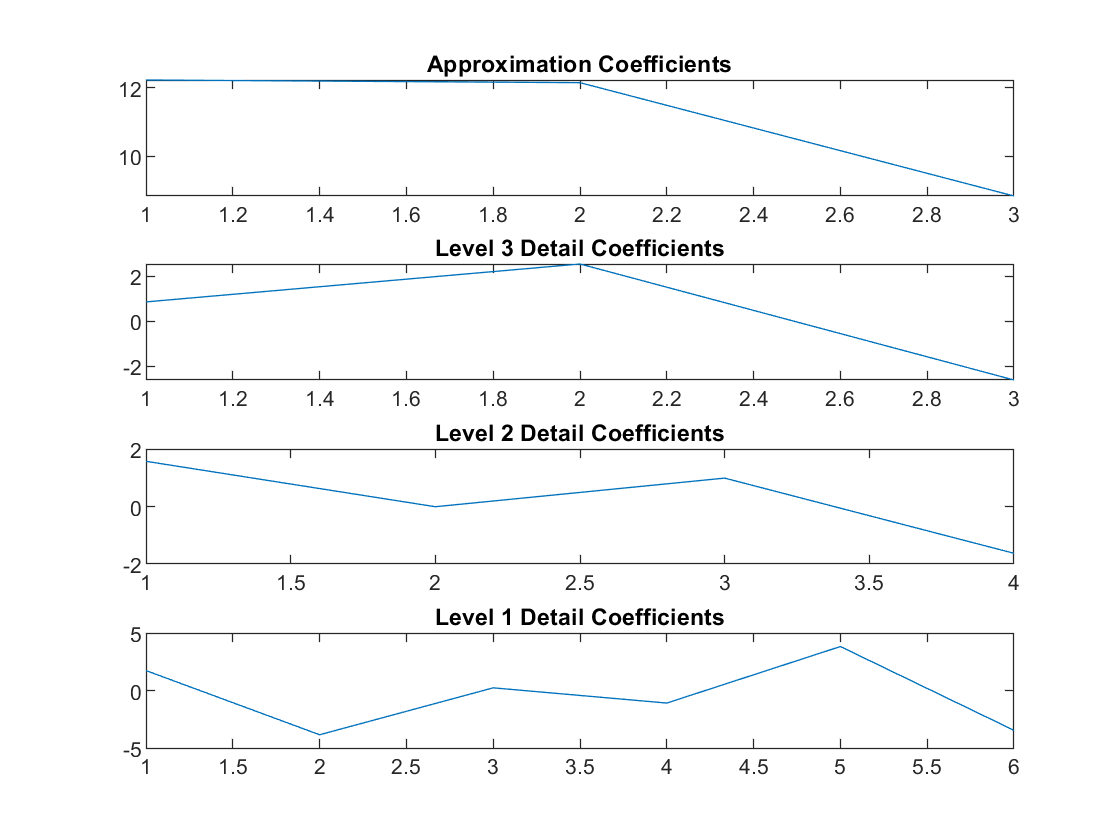





plot(signal)

[c,l] = wavedec(signal,3,'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);


subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

mean([5.625,5])

ans = 5.3125